Plotting the derivative of lhet with respect to t and lhet. This equation was derived by taking the the rate loci without any hits gain 1 minus the rate loci with 1 hit take a second in the other chromosome.

This function attempts to counter the fact that there are half as many targets for the second hit by dividing the second term by 2.

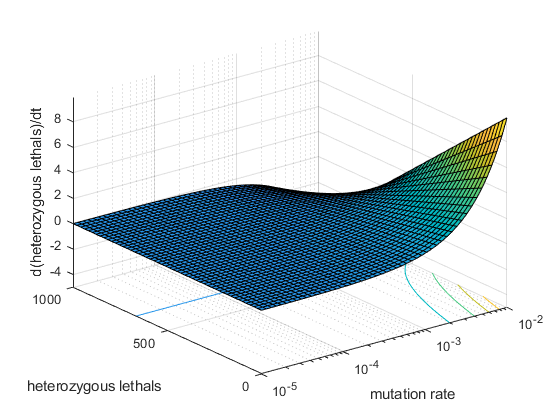

[x,lhet] = meshgrid(logspace(-5, -2), linspace(0,1000,50));
dlhetdt = @(x,lhet) (1000 - lhet).*(x-x.^2) - lhet.*x./2;

figure
surfc(x, lhet, dlhetdt(x,lhet))
set(gca, 'XScale', 'log')
xlabel("mutation rate")
ylabel("heterozygous lethals")
zlabel("d(heterozygous lethals)/dt")
grid on

We cannot use mu substitution directly to solve for lhet because the derivate of mu must be in respect to either x or t and neither alone makes sense. 

we know that lhet(t=0)=0 and lhet(x=0)=0

[x,t] = meshgrid(logspace(-5,-2), linspace(0,500,50));
c = 1

c = 1

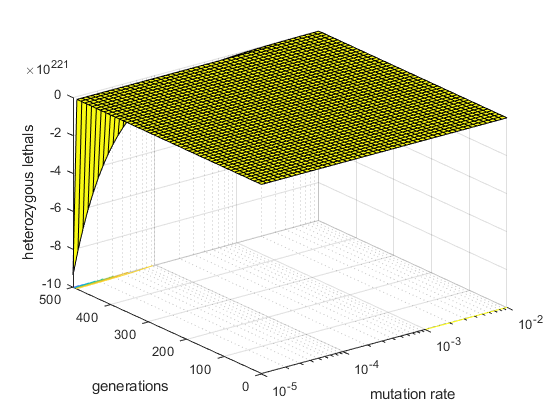

lhet = @(x,t) (1000.*(x-x.^2)-c.*exp(t))./(1.5.*x-x.^2);

figure
surfc(x, t, lhet(x,t))
set(gca, 'XScale', 'log')
xlabel("mutation rate")
ylabel("generations")
zlabel("heterozygous lethals")
grid on

Now that we have the value for lhet we can solve for fitness in terms of x, and lhet. The fitness depends on a constant term alpha that can be tweaked later to adjust for changing enviromental conditions (chemo).

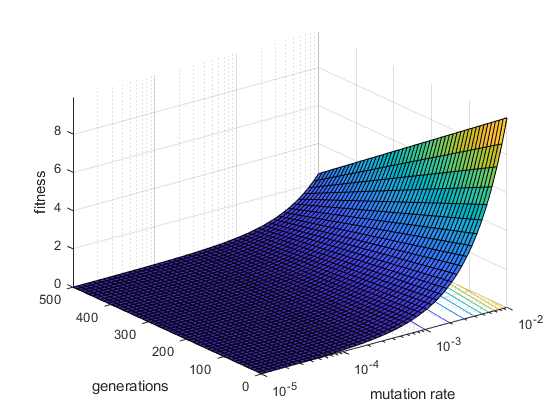

[x,t] = meshgrid(logspace(-5, -2), linspace(0,500,50));
alpha = 1;
fit = @(x,t) alpha.*((1-x.^2).^(1000-lhet(x,t)))*((1-x).^lhet(x,t));

figure
surfc(x, t, dlhetdt(x,t))
set(gca, 'XScale', 'log')
xlabel("mutation rate")
ylabel("generations")
zlabel("fitness")
grid on